# Polinomios de interpolación en el análisis de temperatura

TNov = readmatrix('noviembre.csv','Range','C12:C730')';
tNov = (0:1:length(TNov)-1); 

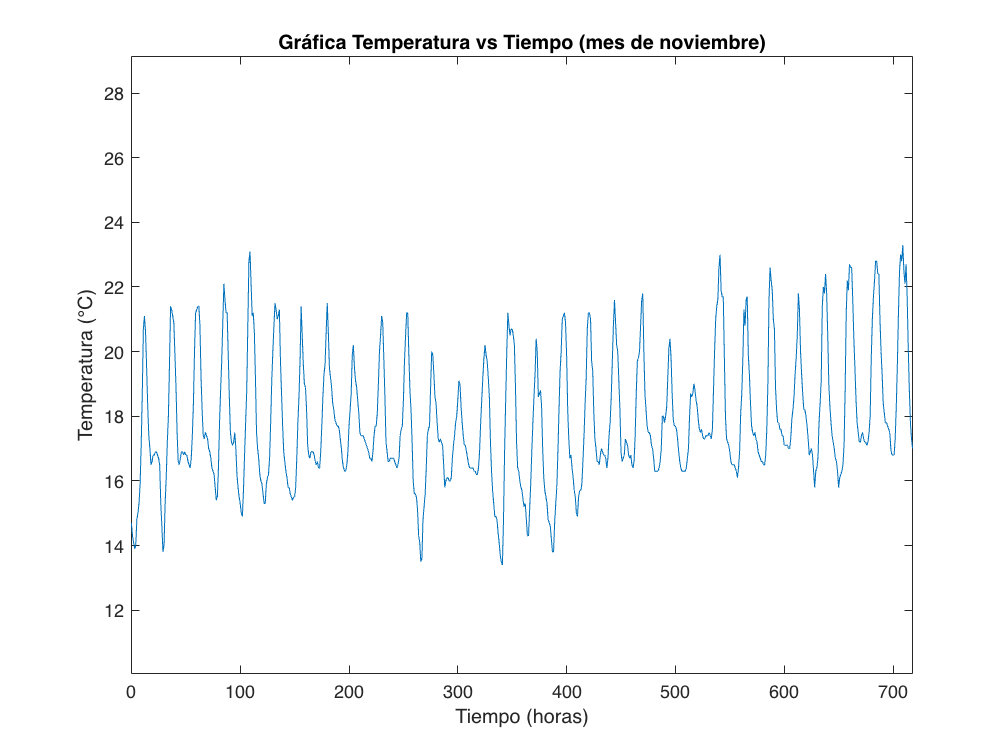

GraficaGeneral(TNov, tNov); hold off;

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12;
    grado = 4;
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end

Hora por defecto: 12


Grado de polinomio de mínimos cuadrados por defecto: 4


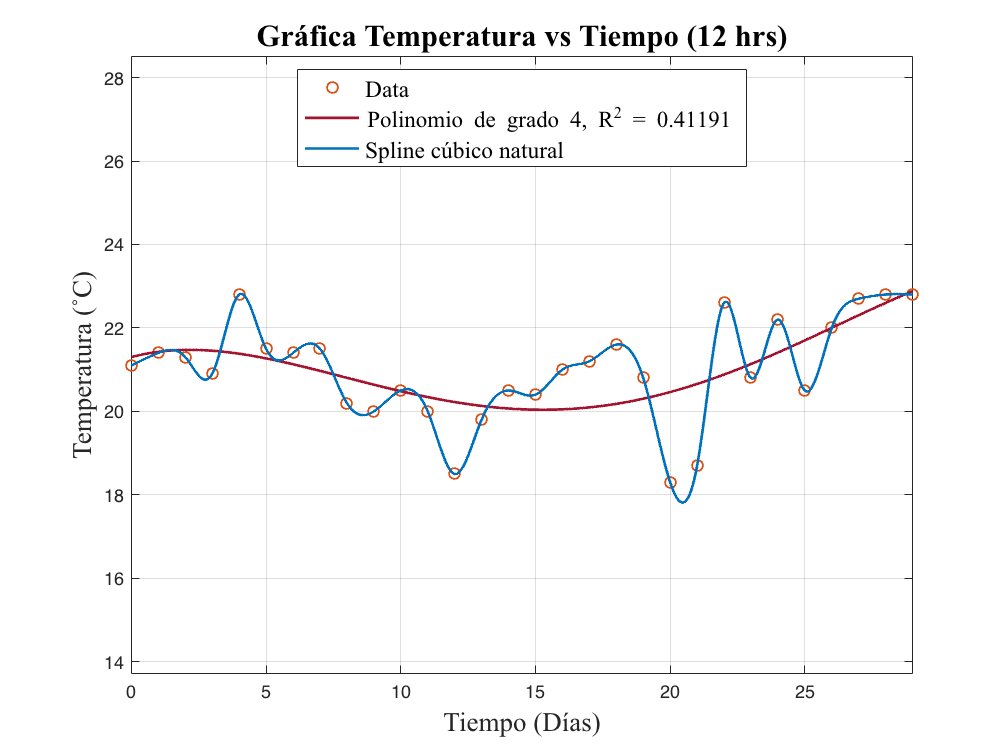

[tNovHora, TNovHora, Sx, P] = GraficaSpline(TNov, hora+1, grado);
hold off

Spline Cúbico Natural:

## 
$$S_i \left(x\right)={a\left(x-x_i \right)}^3 +{b\left(x-x_i \right)}^2 +c\left(x-x_i \right)+d\;\;\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


disp(Sx)

    i     (x-x[i])        a             b            c         d       [x(i), x(i+1)]  
    __    ________    __________    _________    _________    ____    _________________

     0    "(x-0)"      -0.023477            0      0.32348    21.1    "si x ∈ [0, 1]"  
     1    "(x-1)"       -0.28262    -0.070431      0.25305    21.4    "si x ∈ [1, 2]"  
     2    "(x-2)"         1.2539     -0.91828     -0.73566    21.3    "si x ∈ [2, 3]"  
     3    "(x-3)"        -2.1331       2.8435       1.1896    20.9    "si x ∈ [3, 4]"  
     4    "(x-4)"         1.7786      -3.5559      0.47726    22.8    "si x ∈ [4, 5]"  
     5    "(x-5)"       -0.58139         1.78      -1.2986    21.5    "si x ∈ [5, 6]"  
     6    "(x-6)"       -0.45309     0.035849      0.5172

Graficamos el polinomio interpolante de Newton:

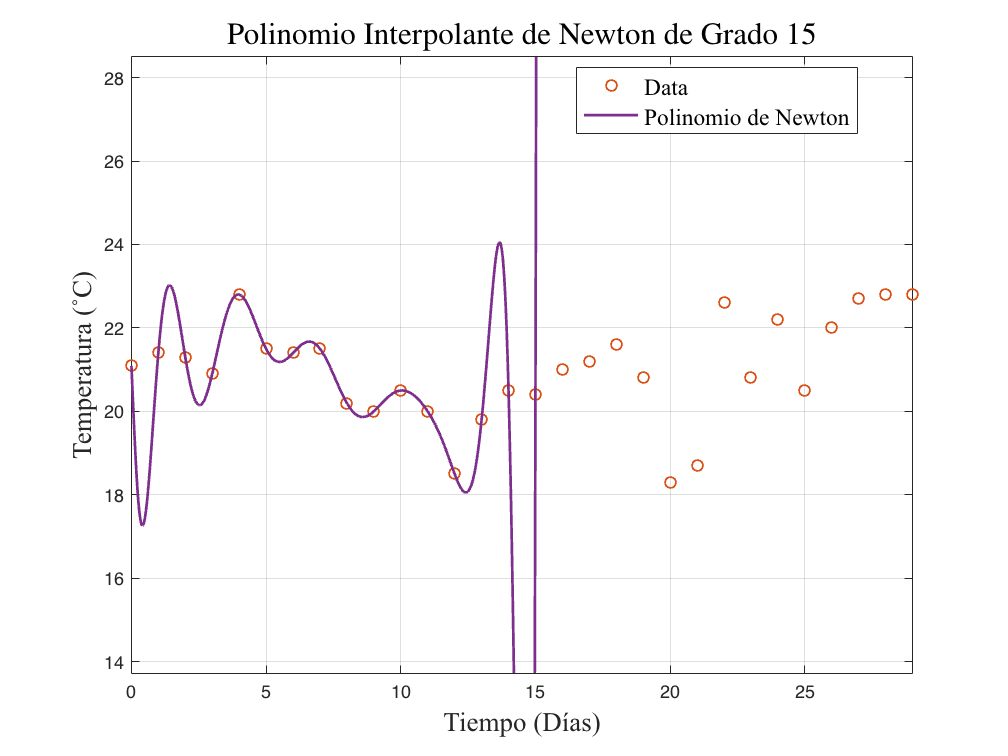

GraficaNewton(tNovHora, TNovHora, ceil(length(tNovHora)/2));

Gráfica de aproximación de Temperatura para los primeros días de diciembre:

TDic = readmatrix('diciembre.csv','Range','C12:C263')';
TDicHora = TDic((hora+1):24:end);
[~, n] = size(TDicHora);

fprintf("Cantidad de Temperaturas reales de diciembre disponibles: %d", n)

Cantidad de Temperaturas reales de diciembre disponibles: 10

while true
    cant_dias = input("Ingrese la cantidad [c] de días de diciembre para estimar (c<=" +int2str(n) + "): ");
    if cant_dias <= n
        break
    end
end

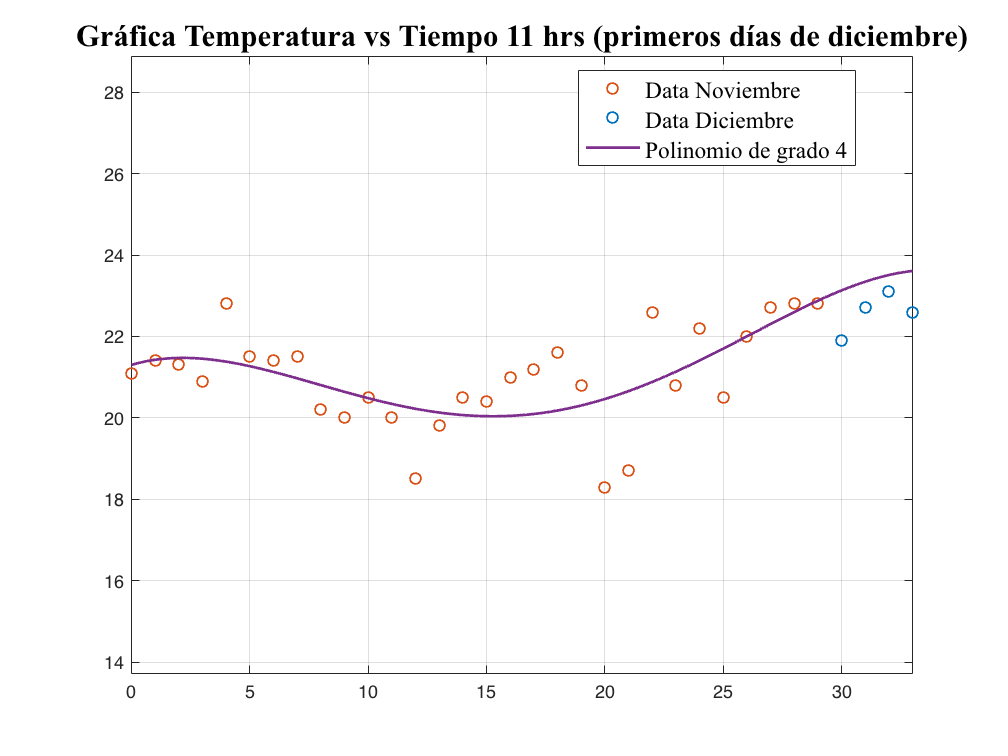

GraficaConDiciembre(TNovHora, TDicHora(1, 1:cant_dias), hora, P, grado, cant_dias);

Taprox = polyval(P, (31:1:(30+cant_dias)));
Treal = TDicHora(1:cant_dias);

Error_absoluto = abs(Treal - Taprox);
disp("Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_absoluto);

Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario
    1.4465    0.8102    0.5101    1.0321



fprintf("Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: %f", norm(Error_absoluto, 2))

Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: 2.018477

Error_relativo = Error_absoluto./Treal;
disp("Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_relativo);

Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.0661    0.0357    0.0221    0.0457



fprintf("Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: %f", norm(Error_relativo, 2))

Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: 0.090608